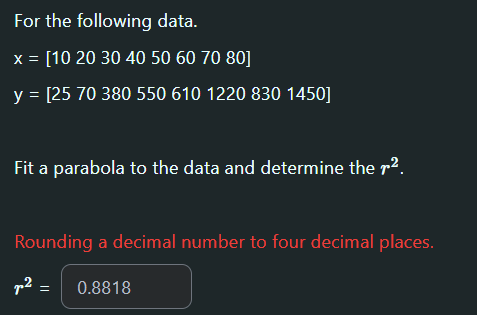

Data

x = [10 20 30 40 50 60 70 80]';
y = [25 70 380 550 610 1220 830 1450]';

%a0 + a1x + a2x^2
z = [ones(size(x)) x x.^2]

z =            1          10         100
           1          20         400
           1          30         900
           1          40        1600
           1          50        2500
           1          60        3600
           1          70        4900
           1          80        6400



a = (z'*z) \ (z'*y);

Sr = sum((y-z*a).^2)

Sr = 2.1379e+05

St = sum((y-mean(y)).^2)

St = 1.8083e+06

r2 = 1 - Sr/St

r2 = 0.8818

syx = sqrt(Sr/(length(x)-length(a)))

syx = 206.7815